# Exercise 2: Simulation Over Terrain

This example demonstrates how to use MATLAB to model a more complex radar scenario and evaluate radar performance in a representative environment with a maneuvering target.

## Scenario Setup and Visualization

load Exercise2Data.mat; % Load the data from Exercise 1 for Exercise 2

Now let's set up the scenario we want to simulate.

Use `geoglobe` to create a globe visualization object named `g`.  Supply the `uifigure` object `fig` as an input argument to create the globe in the relevant figure.  To learn the `geoglobe` syntax, type `doc geoglobe` at the MATLAB command line.  The resulting figure should look like this:

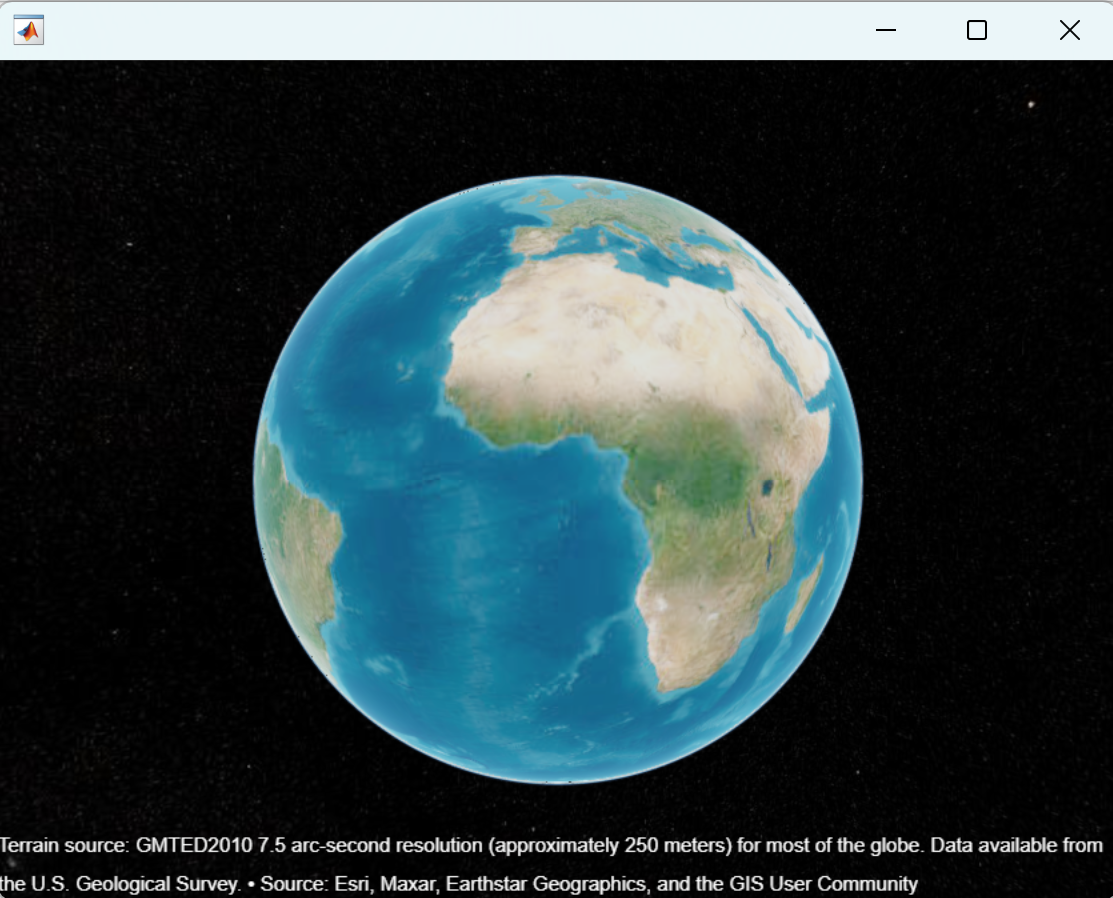

Interact with the globe by clicking and rotating the globe and by scrolling with the mouse wheel.  Click and hold the mouse wheel and drag to change the viewing angle to observe terrain.

fig = uifigure;
g = geoglobe(fig, Basemap="colorterrain");
hold(g,"on")

Change the camera position to better visualize the results.

campos(g,39.77114,-105.62662,6670)
camheading(g,70)
campitch(g,-12)

## Create and Visualize Radar Scenario

This scenario will model a ground based radar system that needs to detect a plane descending behind some mountains in a corkscrew pattern.  The objective is to be able to detect the plane along the entirety of its flight path.

The radar's performance, target characteristics and dynamics, and mountains and terrain will all be considered during this system design activity.

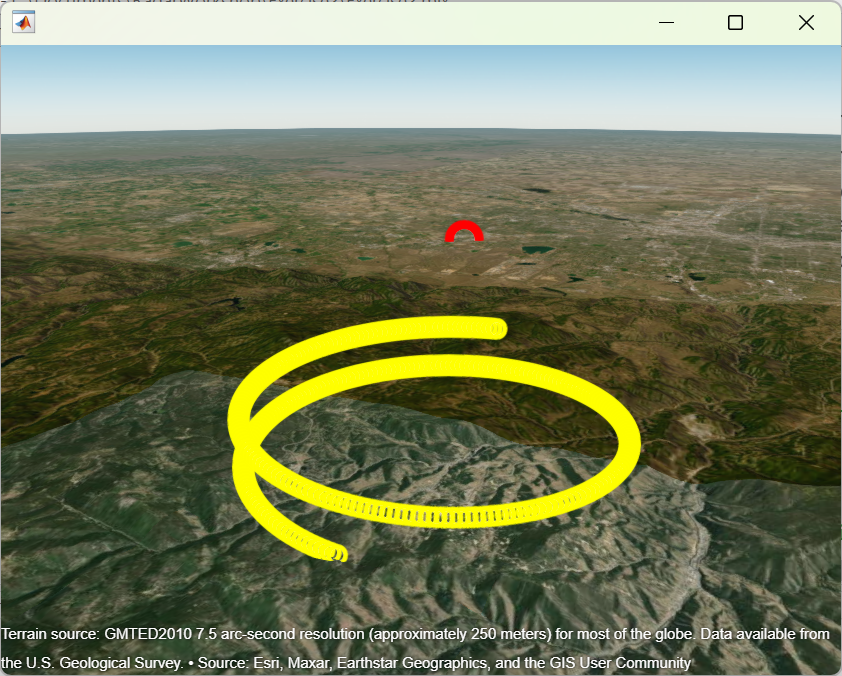

Create a radar scenario using the `radarScenario` function.  The radar scenario object creates and maintains a simulation environment for a radar scenario model.  A radar scenario simulates a 3-D environment containing multiple platforms.  The platforms are the objects you want to simulate, for example, aircraft, ground vehicles, towers, or ships.  These platforms can have sensors like radar, sonar or infrared.  Platforms also act as targets, the sources of signals, or reflectors of signals.  The radar scenario can also contain information about scene geometry; it can be an empty cartesian environment expressed in XYZ coordinates or an earth centered environment with coordinates expressed in latitude, longitude and altitude.  A radar scenario can be used at multiple fidelity levels.  Here, we will use it to do a budget analysis for the performance of our radar system, but it can also be used to define and simulate a statistical model of a radar system, generating detections based on probability of detection and probability of false alarm for a system.  It can also generate IQ that might be received by a monostatic radar system including clutter and target returns.

isEarthCentered = true;  % This is a name/value argument (use the IsEarthCentered=isEarthCentered syntax)
updateRate = 0.1;        % Update rate for the scenario in Hz.  This is a name/value argument (use the UpdateRate=updateRate syntax)
time=(0:299)/updateRate; % Simulation time steps in seconds.
stopTime = time(end);    % Stop time in seconds.  This is a name/value argument (use the StopTime=stopTime syntax)

%---------------------------------------------------------------------------------------------------
% ADD CODE HERE
% Hint: use the 'radarScenario' function to create a radar scenario 
% called "scene".  Type 'doc radarScenario' into the command line
% interface.  The properties weare interested in configuring are 
% "IsEarthCentered", "UpdateRate" and "StopTime".  Name the output 'scene'.

scene = radarScenario(IsEarthCentered=isEarthCentered,UpdateRate=updateRate,StopTime=stopTime); % SOLUTION
%---------------------------------------------------------------------------------------------------

Attribution: SRTM 3 arc-second resolution. Data available from the U.S. Geological Survey.

dtedfile = "n39_w106_3arc_v2.dt1"; % Digital Terrain Elevation Data (DTED)
refl = surfaceReflectivityLand(Model = 'ConstantGamma', Gamma = -20);

%---------------------------------------------------------------------------------------------------
% ADD CODE HERE
% Hint: use the 'landSurface' function to create a land surface called
% "srf".  Type 'doc landSurface' into the command line interface. The
% properties we are interested in configuring are "Terrain" and
% "RadarReflectivity".  Name the output 'srf'.

srf = landSurface(scene, Terrain=dtedfile, RadarReflectivity=refl); % SOLUTION
%---------------------------------------------------------------------------------------------------

Currently, the radar scenario that you have created is empty.  To add platforms to the environment, use the `platform` function and supply the radar scenario defined above as input.  This will populate targets in the scenario environment.  Platforms can be modeled as points or cuboids and contain information about trajectory and motion, signatures that are relevant to specific types of sensors like radar cross section and infrared, and information about what kinds of sensors each of the platforms have.

rdrlat = 39.913756;                % Radar latitude (deg)
rdrlon = -105.118062;              % Radar longitude (deg)
rdrtowerht = 100;                  % Antenna height (m)
rdralt = 1717 + rdrtowerht;        % Radar altitude (m)
rdrpos = [rdrlat, rdrlon, rdralt]; % radar position

% Plot the radar location in the map
h_rdrtraj = geoplot3(g,rdrlat,rdrlon,rdralt,"ro", LineWidth=6, MarkerSize=10);

To see the doc for the 'platform' function in the radar toolbox, click [here](https://www.mathworks.com/help/radar/ref/radarscenario.platform.html?s_tid=doc_ta).

% Add the radar to the radarScenario (called scene)
%---------------------------------------------------------------------------------------------------
% ADD CODE HERE
% Hint: use the 'platform' function to add the radar platform to the
% scenario.  Name the output 'rdrplatform'.  The position is specified by a
% row vector of lat, lon, alt as above.  Specify the radar position as a
% name value pair (e.g., Position=pos).  Learn more about the 'platform'
% function by clicking on the link in the text above.

rdrplatform = platform(scene, Position=rdrpos); % SOLUTION
%---------------------------------------------------------------------------------------------------

In the below function, define the target dynamics for the duration of the simulation.  Make the time step between subsequent evaluation points 10 seconds by setting the update rate to 0.1 Hz.  If you are interested in seeing how the target trajectory is defined, find the helper function at the end of the file.

[ttraj, tlat, tlon, talt] = DefineTarget(time, updateRate);

Plot the ground truth trajectory over the terrain.  Use the `geoplot3` function to plot the trajectory of the target.  Use the trajectory information supplied above (`tlat`, `tlon`, `talt`) to plot the trajectory in 3 dimensions on the globe.  Specify that the points should be yellow and circular by using the argument `"yo"` for the `LineSpec` argument in the function.  

trajPlot = geoplot3(g,tlat,tlon,talt,"yo", LineWidth=3);

Let's add the target platform to the radar scenario.  Notice in this code, a radar cross section is specified by using the "Signatures" property of the platform and supplying an `rcsSignature` object.  This radar cross section can be generated simply as below, can be generated using EM solver tools in MATLAB, or can be imported from other simulation tools or empirical data.

In addition, a trajectory is specified for the platform.  This trajectory is a `geoTrajectory` object that specifies waypoints in LLA coordinates.  There are also cartesian `waypointTrajectory` and `kinematicTrajectory` objects for specifying waypoints in cartesian coordinates and for specifying kinematics of a platform like position, velocity, and acceleration, respectively.  These objects are convenient for radar systems engineers as they enable the accurate modeling of vehicle dynamics, including position, velocity, acceleration and orientation without having a high fidelity design model of the system.  In this manner, the movement of a platform in a scenario can be accounted for without complex platform models.

If you are interested, type `ttraj` in the MATLAB command window to examine some of the properties of the trajectory object that enable this modeling.

The radar cross section (RCS) for an aircraft is typically from 1 to 10 square meters. For this example, consider the aircraft as an isotropic point target with an RCS of 10 square meters.

trcs = pow2db(rcs);          % Target RCS (dBsm)

tplatform = platform(scene, Trajectory=ttraj, ...
    Signatures={rcsSignature(Azimuth=[-180 180],Elevation=[-90 90],Pattern=trcs)});

## Run Radar Scenario Simulation

Running a radar scenario is easy using a while loop.  The `advance` function of the radar scenario will return `true` while there are still things happening in the scenario or until the specified scenario completion time has been reached.  The radar scenario has a built-in sense of time.  In this configuration, we specified the update rate for the scenario as 0.1 Hz.  Alternatively, by specifying the update rate as "0", the radar scenario will automatically take variable sized steps to be sure each sensor in the model executes at its specified update rate.  The trajectories of the platforms are interpolated between waypoints to provide accurate kinematic information for the platforms at that moment in time.

restart(scene)

% Initialize a variable to keep track of the ranges between targets
% throughout the scenario simulation
trange = zeros(length(time), 1);

% Initialize a variable to keep track of target visibility behind terrain
% throughout the scenario simulation
isVisible = false(size(time));

% Keep track of the index of each of the above variables we are assigning
% to throughout the duration of the simulation
idx = 1;

% Run the radar scenario using a while loop and the 'advance' function of
% the radarScenario object
while advance(scene)
    % Get the positions of each of the platforms (the radar and the target)
    % in geodetic coordinates at this time step
    tpose = pose(tplatform,CoordinateSystem="Geodetic");
    tpos = tpose.Position;
    rpose = pose(rdrplatform,CoordinateSystem="Geodetic");
    rpos = rpose.Position;
    
    % Determine whether the target is occluded from the radar by the
    % terrain model in the scenario.  This function returns 'true' if the
    % target is occluded and false if it is visible.
    isVisible(idx) = ~boolean(occlusion(scene.SurfaceManager, rpos, tpos));

    % Calculate the range between the radar and the target in meters based
    % on the radar and target geodetic coordinates
    trange(idx) = llarangeangle(rpos,tpos, 1);

    % Update the index for variable assignment
    idx = idx+1;
end

## Visualize Line of Sight Along Trajectory

Next, clear the plot of the target trajectory previously created so new plots with information from the scenario simulation can be generated.

delete(trajPlot);

Now, visualize the occlusion of the target throughout the scenario simulation.  The green points are where the target is visible to the radar and the black points are where the target is occluded from the radar by terrain.

visibilityPlot = PlotVisibility(g, isVisible, tlat, tlon, talt);

## Calculate SNR and Detectability Along Trajectory

Next, use the functions from part 1 to calculate the received SNR for the radar throughout the duration of the simulation.  Use the `radareqsnr` function to find the signal to noise ratio of the received pulse.  The function is vectorized, so it can take a column vector of ranges as input.

%---------------------------------------------------------------------------------------------------
% ADD CODE HERE
% Hint: use the 'radareqsnr' function to determine the signal to noise
% ratio of the received pulses. Supply lambda, trange, peakPower,
% pulseWidth, rcs and antennaGain as inputs.  Type 'doc radareqsnr' into
% the command line interface for more information.  Name value properties
% we are interested in are "RCS" and "Gain".  Name the output 'tsnr'.

% Use the variable from the first exercise to parameterize the function and
% supply the ranges generated using the radarScenario as the ranges of
% interest.  The ranges are called 'trange'.  Wavelength is called
% 'lambda', power called 'pt', and pulse width called 'tau'.  The RCS of
% the target is called 'rcs' and the gain of the antenna called 'gain'.

tsnr = radareqsnr(lambda,trange,pt,tau,RCS=rcs,Gain=gain); % SOLUTION
%---------------------------------------------------------------------------------------------------

% If the target is occluded at a time step, set the received SNR
% artificially to -inf to represent no pulse received (the actual effects
% of terrain can be modeled with higher fidelity if desired).
tsnr(~isVisible) = -inf;

Next, plot the SNR along the trajectory. 

% Plot the SNR over the aircraft trajectory
snrPlot = PlotSNR(g, tsnr, visibilityPlot);

As the aircraft performs the corkscrew maneuver, the SNR of the received signal might vary, as shown in the figure.  The radar has an unobstructed view of the aircraft if there is a line-of-sight path.  The black portion of the trajectory indicates that there is no line-of-sight path between the aircraft and the radar.

For the surveillance radar, the desired performance index is a probability of detection (Pd) of 0.9 and probability of false alarm (Pfa) below 1e-6.  Let's start by looking at detectibility from 1 pulse in the return.  We will evaluate how many pulses to integrate in the next step.  A good approximation of the minimum SNR needed for a detection at the specified Pd and Pfa can be computed by the `detectability` function.

pd = 0.9;
pfa = 1e-6;
numPulses = 1;

%---------------------------------------------------------------------------------------------------
% ADD CODE HERE
% Hint: Use the 'detectability' function to calculate the minimum SNR
% required for a single pulse to detect the target with your radar system.
% Type 'doc detectability' into the command line for more information.
% Supply the probability of detection, probability of false alarm, and
% number of pulses as input arguments.  Name the output 'minimumSNR'.

minimumSNR = detectability(pd,pfa,numPulses); % SOLUTION
%---------------------------------------------------------------------------------------------------

## Where can I detect the aircraft?

Observe in which part of the trajectory the target is detectable (shown in green) given the minimum SNR requirement. Note that the existence of a line-of-sight link does not guarantee that the target is detectable.

detectabilityPlot = PlotDetectable(minimumSNR, tsnr, snrPlot);

#### Exercise Questions: What is the minimum signal to noise ratio required? Can the target be detected for the entirety of its flight?

## Conclusion

The radar is able to detect some of the aircraft's trajectory.  There are regions where it cannot detect the aircraft, however.  There are two main reason for this: occlusion and radar performance.  In the areas where the aircraft is not occluded by the terrain, can we improve the radar's performance so that the target is detectable?  We will investigate that in exercise 3.

## Helper Functions

Consider a large commercial aircraft as the target. Assume the aircraft trajectory is a corkscrew maneuver, where the aircraft descends rapidly in a spiral.

function [ttraj, tlat,tlon, talt] = DefineTarget(time, updateRate)
    tlat0 = 39.80384;                    % Target initial latitude (deg)
    tlon0 = -105.49916;                  % Target initial longitude (deg)
    tht0 = 3000;                         % Target initial height (m)
    azs = linspace(1, 540, numel(time)); % Target azimuth (deg)
    r = 5000;                            % Target slant range (m)
    
    % Convert from polar coordinates to Cartesian East, North, Up (ENU).
    [X,Y] = pol2cart(deg2rad(azs),r);
    
    % Convert ENU to geodetic.
    Z = linspace(2000, 0, numel(azs));
    wgs84 = wgs84Ellipsoid;
    [tlat,tlon,tht] = enu2geodetic(X,Y,Z,tlat0,tlon0,tht0,wgs84);
    
    % Define the target altitude.
    talt = tht - egm96geoid(tlat,tlon); % Target altitude (m)

For simplicity, assume the waypoints are obtained at a constant sampling rate of 0.1 Hz. The trajectory can be generated using `geoTrajectory` with positions specified as latitude, longitude, and altitude.

    ttraj = geoTrajectory([tlat.' tlon.' talt.'],time,SampleRate=updateRate);
end

Plot the visibility of the aircraft along its trajectory.

function visibilityPlot = PlotVisibility(g, isVisible, tlat, tlon, talt)
    visibleColor = 'g';
    occludedColor = 'k';
    color = repmat(occludedColor, 1, length(isVisible));
    color(isVisible) = visibleColor;

    visibilityPlot = zeros(size(isVisible));

    for ii = 1:length(isVisible)
        visibilityPlot(ii) = geoplot3(g, tlat(ii), tlon(ii), talt(ii), Marker='o', LineWidth=2, MarkerSize=1,...
            Color=color(ii));
    end
end

Plot the signal to noise ratio of signals returned from the aircraft along its trajectory.

function visibilityPlot = PlotSNR(g, tsnr, visibilityPlot)
    tsnr_finiteidx = ~isinf(tsnr);
    tsnr_cidx = zeros(size(tsnr));
    cmap = colormap(g);
    numclvls = size(cmap,1);
    tsnr_cidx(tsnr_finiteidx) = discretize(tsnr(tsnr_finiteidx),numclvls-1);
    tsnr_cidx(~tsnr_finiteidx) = numclvls;
    
    for m = 1:numel(tsnr)
        if tsnr_finiteidx(m)
            set(visibilityPlot(m),Color=cmap(tsnr_cidx(m),:));
        else
            set(visibilityPlot(m),Color="k");
        end
    end
end

Plot the detectability of the aircraft along its trajectory.

function snrPlot = PlotDetectable(minimumSNR, tsnr, snrPlot)
    isdetectable = tsnr >= minimumSNR;

    for m = 1:numel(tsnr)
        if ~isinf(tsnr(m))
            if isdetectable(m)
                set(snrPlot(m),Color="g");
            else
                set(snrPlot(m),Color="r");
            end
        else
            set(snrPlot(m),Color="k");
        end
    end
end